## Problema 3

A column is made of a certain material with Young modulus $E = 181\times 10^{6}\, \text{kN/m}^{2}$ The geometry of the column is shown in the figure. We wish to analyze the column for displacements using the FEM.

                                            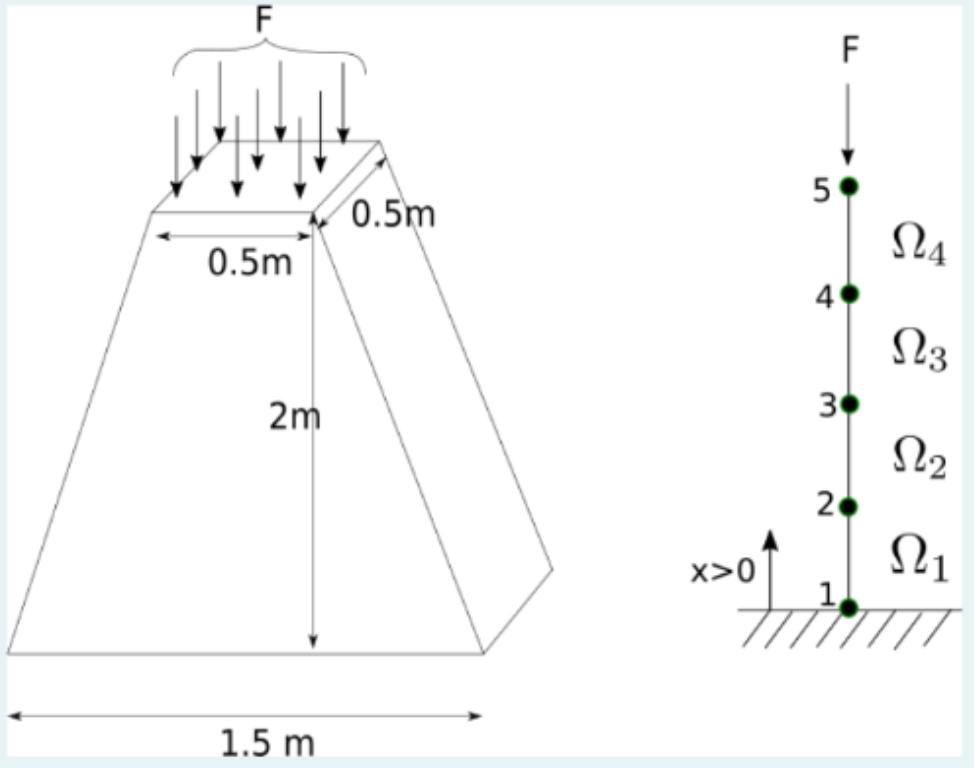

The column is indeed a three-dimensional structure. However, we wish to approximate the column as one dimensional. To this end, we represent the distributed force at the top of the column as a point force $F = 5\, \text{kN}$.

    The weight of the material is represented by the body force per unit lenght: $f(x) = -6.25 (3 - x)\ \text{kN/m}$. The governing differential equation for the problem is given by $-\frac{\mathrm{d}}{\mathrm{d} x}\left(E A(x) \frac{\mathrm{d} u}{\mathrm{d} x}\right) = f(x)$ where $A(x)$ is the cross-sectional area.

    Consider a mesh with $4$ linear elements of equal length $h = 0.5\; \text{m}$.

### Solution

We give the formulae needed to solve the exercise, before solving the quaetions.

#### Formulae

Shape functions of  the linear 1D element $\Omega^{e}$:

                                            
$$\psi^{e}_{1}(x) = \frac{x-x^{e}_{2}}{x^{e}_{1} - x^{e}_{2}},\qquad\qquad
\psi^{e}_{2}(x) = \frac{x-x^{e}_{1}}{x^{e}_{2} - x^{e}_{1}}.\qquad\qquad
$$


Components of the local stiffness matrix.

                                          
$$K^{e}_{i,j} = \int_{x^{e}_{1}}^{x^{e}_{2}} a_{1}(x) \frac{\mathrm{d}\psi^{e}_{i}}{\mathrm{d} x}(x) \frac{\mathrm{d}\psi^{e}_{j}}{\mathrm{d} x}(x)\; \mathrm{d} x,$$


$i, j = 1, 2$. In this case in point, $a_{1}(x) = E A(x)$, and we've seen in class, that for this truncated-wedge shped column, the sectional area changes linearly with the height $x$, so we can write $A(x) = \alpha x + \beta$. As, for $x = 0$, $A(0) = \frac{3}{2}\times \frac{1}{2} = \frac{3}{4}$ and, for $x = 2$, $A(2) = \frac{1}{2}\times\frac{1}{2} = \frac{1}{4}$. Therefore,

                                        
$$\begin{array}{lcr}
0 \alpha + \beta &\!\!\!\!\!\!\! = \!\!\!\! & \frac{3}{4},\\
2 \alpha + \beta &\!\!\!\!\!\!\! = \!\!\!\! &\frac{1}{4},
\end{array}
$$


 and, solving the system we get $\alpha = - \frac{1}{4}$, $\beta = \frac{3}{4}$. So,

                                       $A(x) = \frac{3}{4} - \frac{\alpha}{4}$.

Hence, the components of matrix $K^{e}$ are,

                                        
$$\begin{array}{rcl}
K^{e}_{1,1} &\!\!\!\!\!\!\!=\!\!\!\!
& \int_{x^{e}_{1}}^{x^{e}_{2}} E A(x) 
\frac{\mathrm{d}\psi^{e}_{1}}
{\mathrm{d}x}(x) \frac{\mathrm{d}\psi^{e}_{1}}
{\mathrm{d}x}(x)\mathrm{d} x \\
&\!\!\!\!\!\!\!=\!\!\!\!&
\frac{E}{\left(x^{e}_{2}-x^{e}_{1}\right)^{2}}\int_{x^{e}_{1}}^{x^{e}_{2}}
\left(\alpha x + \beta\right)\mathrm{d} x =
\frac{E}{h^{e}}\left(\alpha\frac{x^{e}_{1} + x^{e}_{2}}{2} + \beta\right)
= K^{e}_{2,2},\\
K^{e}_{1,2} &\!\!\!\!\!\!\!=\!\!\!\!& K^{e}_{2,1} = - K^{e}_{1,1},
\end{array}$$


being $h^{e} = x^{e}_{2} - x^{e}_{1}$, the length of the element $\Omega^{e}$, for $e = 1,2,3,4$. Therefore:

                                        
$$\begin{array}{c}
K^{1} = \displaystyle\frac{\alpha E}{2}\left(\!
\begin{array}{rr}
1 & -1\\
-1 & 1
\end{array}\!\right) 
+ 2E\beta\left(\!
\begin{array}{rr}
1 & -1\\
-1 & 1\end{array}
\!\right),\\[15pt] 
K^{2} = \displaystyle\frac{\alpha E}{2}\left(\!\begin{array}{rr}
3 & -3\\
-3 & 3
\end{array}\!\right) + 2E\beta\left(
\!\begin{array}{rr}
1 & -1\\
-1 & 1\end{array}\!\right),\\[15pt]
K^{3} = \displaystyle\frac{\alpha E}{2}\left(\!\begin{array}{rr}
5 & -5\\
-5 & 5
\end{array}\!\right) + 2E\beta\left(
\!\begin{array}{rr}
1 & -1\\
-1 & 1\end{array}\!\right),\\[15pt]
K^{4} = \displaystyle\frac{\alpha E}{2}\left(\!\begin{array}{rr}
7 & -7\\
-7 & 7
\end{array}\!\right) + 2E\beta\left(
\!\begin{array}{rr}
1 & -1\\
-1 & 1\end{array}\!\right).
\end{array}
$$


Then, the coupled stiffness matrix is,

                                        
$$$$
K = \frac{\alpha E}{2}
\left(\!\begin{array}{rrrrr}
1 & -1 & & &\\
-1 & 4 & -3 & & \\
& -3 & 8 & -5 & \\
& & -5 & 12 & -7 \\
& & & -7 & 7
\end{array}\!\right) +
2 E \beta\, \left(\!
\begin{array}{rrrrr}
1 & -1 & & &\\
-1 & 2 & -1 & &\\
& -1 & 2 & -1 &\\
& & -1 & 2 & -1\\
& & & -1 & 1
\end{array}
\!\right),
$$


with (recall) $E = 181\times 10^{6}\, \text{kN/m}^{2}$, $\alpha = -1/4$, and $\beta = 3 / 4$. Next, to compute the components of the body force vector, we know that these are given by the quadratures,

                                        
$$F^{e}_{i} = \int_{x^{e}_{1}}^{x^{e}_{2}} f(x) \psi^{e}_{i}(x)\mathrm{d} x,
$$


$i=1,2$. In this exercise $f(x)$ is an affine function, i.e., a function of type $f(x) = \gamma x + \delta$, with coefficients: 

                                        
$$\gamma = 6.25,\quad \delta = -6.25\times 3 = -18.75.$$


After computing the integrals we get,

                                       
$$\begin{array}{l}
    F^{e}_{1} =
        \displaystyle\int_{x^{e}_{1}}^{x^{e}_{2}}
        \left(\gamma x + \delta\right)
        \frac{x-x^{e}_{2}}
        {x^{e}_{1}-x^{e}_{2}}\mathrm{d} x =
        h^{e}\left(
        \gamma\frac{2x^{e}_{1} + x^{e}_{2}}{6}
        + \frac{\delta}{2}\right),\\[15pt]
    F^{e}_{2} =
        \displaystyle\int_{x^{e}_{1}}^{x^{e}_{2}}
        \left(\gamma x + \delta\right)
        \frac{x-x^{e}_{1}}
        {x^{e}_{2}-x^{e}_{1}}\mathrm{d} x =
        h^{e}\left(
        \gamma\frac{x^{e}_{1} + 2 x^{e}_{2}}{6}
        + \frac{\delta}{2}\right),
\end{array}
$$


being $h^{e} = x^{e}_{2} - x^{e}_{1} = 1 / 2$, the length of the element $\Omega^{e}$, for$e = 1,2,3,4$. Therefore:

                                       
$$\begin{array}{cccc}
F^{1} = \displaystyle \frac{1}{2}\left(
    \begin{array}{c}
    \displaystyle \frac{\gamma}{12} + \frac{\delta}{2}\\[4pt]
    \displaystyle \frac{\gamma}{6} + \frac{\delta}{2}
    \end{array}\right),&
F^{2} = \displaystyle \frac{1}{2}\left(
    \begin{array}{c}
    \displaystyle \frac{\gamma}{3} + \frac{\delta}{2}\\[4pt]
    \displaystyle \frac{5\gamma}{6} + \frac{\delta}{2}
    \end{array}\right),&
F^{3} = \displaystyle \frac{1}{2}\left(
    \begin{array}{c}
    \displaystyle \frac{7\gamma}{12} + \frac{\delta}{2}\\[4pt]
    \displaystyle \frac{2\gamma}{3} + \frac{\delta}{2}
    \end{array}\right), &
F^{4} = \displaystyle \frac{1}{2}\left(
    \begin{array}{c}
    \displaystyle \frac{5\gamma}{6} + \frac{\delta}{2}\\[4pt]
    \frac{11\gamma}{12} + \frac{\delta}{2}
    \end{array}\right).
\end{array}
$$


Hence, after coupling the local vectors above, it turns out that the *global* body force vector is given by,

                                        
$$F = \left(\begin{array}{c}
F^{1}_{1}\\
F^{1}_{2} + F^{2}_{1}\\
F^{2}_{2} + F^{3}_{1}\\
F^{3}_{2} + F^{4}_{1}\\
F^{4}_{2}
\end{array}\right) =
\frac{\gamma}{24}\left(
\begin{array}{c}
1\\ 6\\ 12\\ 18\\ 11 
\end{array}
\right) + 
\frac{\delta}{4}
\left(
\begin{array}{c}
1\\ 2\\ 2\\ 2\\ 1
\end{array}
\right).
$$


with (recall) $\gamma = 6.25$ and $\delta = -18.75$.

#### Questions          

(a) *(3 points)* The value $K_{2,3}$ of the stiffness matrix is:

- Empty answer (no penalty)

- 
$$\texttt{-2.0362e+08}\; \text{m}$$


- 
$$\texttt{-1.8326e+08}\; \text{m}$$


- 
$$\texttt{-2.2806e+08}\; \text{m}$$


- 
$$\texttt{-2.2602e+08}\; \text{m}$$


clearvars
close all

E = 1.81e8;              %kN/m^2 
pointForceAtTop = 5.0;   %kN (pointing downwards)

alpha = -1/4; beta = 3/4;
gamma = 6.25; delta = -18.75;

elem = [1, 2;
    2, 3;
    3, 4;
    4, 5];

h = 0.5; %Length of the elements

nodes = (0:h:2)';

numElem = size(elem,1);
numNodes = size(nodes,1);

K = zeros(numNodes);
F = zeros(numNodes,1);
Q = zeros(numNodes,1);

%Couple the local stiffness matrix to build the global stiffness matrix
for e = 1:numElem
    rows = [elem(e,1), elem(e,2)];
    cols = rows;
    %x1 and x2 are the positions of the 1st and 2nd nodes of element
    %\Omega^{e}
    x1 = nodes(rows(1)); x2 = nodes(rows(2));
    %Local stiffnesss matrix of element Omega^{e}:
    Ke11 = E * (alpha * (x1 + x2)/2 + beta)/h; Ke22 = Ke11; 
    Ke12 = -Ke11; Ke21 = -Ke11;
    Ke = [Ke11, Ke12; Ke21, Ke22]; 
    %Local body force vector of element Omega^{e}:
    Fe = h * [gamma * (2*x1 + x2)/6 + delta/2;
        gamma * (x1 + 2*x2)/6 + delta/2]; 
    K(rows,cols) = K(rows,cols) + Ke;
    F(rows) = F(rows) + Fe;
end
fprintf("(a) K(2,3) = %.4e m\n",K(2,3))

(a) K(2,3) = -2.0362e+08 m


(b) *(3 points)*

%Fixed Nodes
fixedNods = 1;
freeNods = setdiff(1:numNodes, fixedNods);

%Boundary Conditions
% Natural B.C.
Q(5) = -pointForceAtTop;
%Essential B.C
u = zeros(numNodes,1);
u(1) = 0.0;

%Reduced system
Km = K(freeNods,freeNods);
Fm = F(freeNods) + Q(freeNods) - K(freeNods,fixedNods)*u(fixedNods);

%Solution of the reduced system
u(freeNods) = Km \ Fm; 
fprintf("(b) Approximate solution at x = 2: u_approx(2) = %.4e m\n", u(end))

(b) Approximate solution at x = 2: u_approx(2) = -3.2297e-07 m


fprintf("Hint: The approximate solution at x = 1 is u_approx(1) = %.4e m\n", u(3))

Hint: The approximate solution at x = 1 is u_approx(1) = -1.8998e-07 m


% Elongation of the last element
elongation = u(5) - u(4);
fprintf("Elongation of the last element: %.4e m\n", elongation)

Elongation of the last element: -6.0313e-08 m


***Some checks***

*Global stifness matrix:*

matrixKComputedByHand = ...
   alpha * E * [1, -1, 0, 0, 0;
                  -1, 4, -3, 0, 0;
                  0, -3, 8, -5, 0;
                  0, 0, -5, 12, -7;
                  0, 0, 0, -7, 7] / 2 + ...
   2 * E * beta * [1, -1, 0, 0, 0;
                  -1, 2, -1, 0, 0;
                   0, -1, 2, -1, 0;
                   0, 0, -1, 2, -1;
                   0, 0, 0, -1, 1];

format short e
format compact
% Display the results of the stiffness matrices
fprintf('Matrix K computed by hand:\n');

Matrix K computed by hand:


fprintf('%16.8e%16.8e%16.8e%16.8e%16.8e\n',matrixKComputedByHand);

  2.48875000e+08 -2.48875000e+08  0.00000000e+00  0.00000000e+00  0.00000000e+00
 -2.48875000e+08  4.52500000e+08 -2.03625000e+08  0.00000000e+00  0.00000000e+00
  0.00000000e+00 -2.03625000e+08  3.62000000e+08 -1.58375000e+08  0.00000000e+00
  0.00000000e+00  0.00000000e+00 -1.58375000e+08  2.71500000e+08 -1.13125000e+08
  0.00000000e+00  0.00000000e+00  0.00000000e+00 -1.13125000e+08  1.13125000e+08


fprintf('Matrix K computed using the loop running through the elements:\n');

Matrix K computed using the loop running through the elements:


fprintf('%16.8e%16.8e%16.8e%16.8e%16.8e\n',K');

  2.48875000e+08 -2.48875000e+08  0.00000000e+00  0.00000000e+00  0.00000000e+00
 -2.48875000e+08  4.52500000e+08 -2.03625000e+08  0.00000000e+00  0.00000000e+00
  0.00000000e+00 -2.03625000e+08  3.62000000e+08 -1.58375000e+08  0.00000000e+00
  0.00000000e+00  0.00000000e+00 -1.58375000e+08  2.71500000e+08 -1.13125000e+08
  0.00000000e+00  0.00000000e+00  0.00000000e+00 -1.13125000e+08  1.13125000e+08


fprintf('Norm of the difference: %.e\n', norm(K - matrixKComputedByHand))

Norm of the difference: 0e+00


*Global body force vector*

bodyForceVectorComputedByHand = gamma * [1; 6; 12; 18; 11] / 24 + ...
    delta * [1; 2; 2; 2; 1] / 4;
fprintf('Body force vector F computed by hand:\n')

Body force vector F computed by hand:


fprintf('%16.8e\n',bodyForceVectorComputedByHand')

 -4.42708333e+00
 -7.81250000e+00
 -6.25000000e+00
 -4.68750000e+00
 -1.82291667e+00


fprintf('Body force vector F computed using the loop running through the elements:\n');

Body force vector F computed using the loop running through the elements:


fprintf('%16.8e\n',F')

 -4.42708333e+00
 -7.81250000e+00
 -6.25000000e+00
 -4.68750000e+00
 -1.82291667e+00


fprintf('Norm of the difference: %.e\n', norm(F-bodyForceVectorComputedByHand))

Norm of the difference: 0e+00
